%Raffredamento di una sbarra di rame con l = 1 e D = 1 (problema
%adimensionale)
u = 0;
D = 1;

t_start = 0;
t_final = 1/pi^2;
dt = t_final/10000;
n_step_time = (t_final-t_start)/dt+1;

x_start = 0;
x_final = 1;
dx = 0.01;
n_step_space = (x_final - x_start)/dx+1;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (dt <= dx/u )
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability respected!


% La sbarra parte da una temperatura e la lascio raffredare
T = zeros(n_step_space,n_step_time);
T_inizial = 1;
for i = 2:n_step_space-1
    T(i, 1) = T_inizial;
end

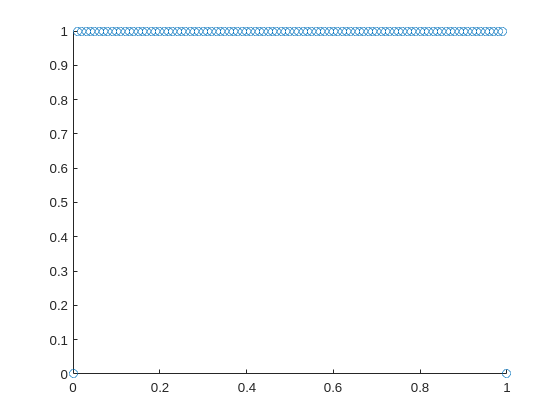


scatter(x, T(:,1))    

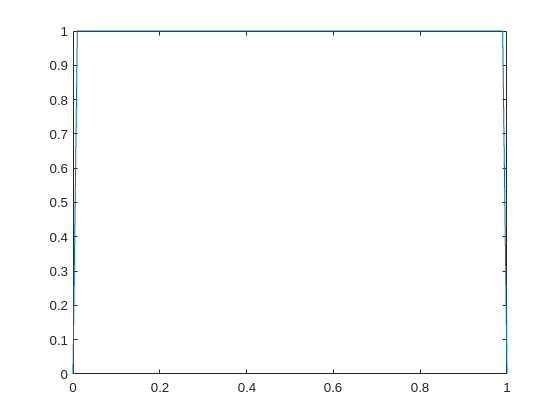

plot(x, T(:,1))

for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;
    end
end

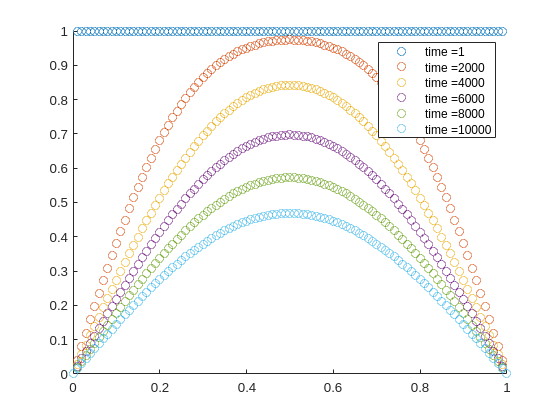

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

step = (n_step_time-1)/5;

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*step));
end

scatter(x, T(:, 1))
hold on
for j = 1:5
    scatter(x, T(:,(j)*step));
    hold on
end
legend(Legend)
hold off

T_sol_exact = zeros(n_step_space, n_step_time);
T_sol_exact(:,1) = T(:,1);
k_max = 5;

for j = 2:n_step_time
    tempo = (j-1)*dt;
    for i = 1:n_step_space
        spazio = (i-1)*dx;
        for k = 1:k_max
            T_sol_exact(i,j) = T_sol_exact(i,j) + ...
                exp(-(2*k-1)^2 * pi^2 * tempo)*...
                sin((2*k-1)*pi*spazio)/...
                (2*k-1);
        end
        T_sol_exact(i,j) = (4*T_inizial/pi)*T_sol_exact(i,j);
    end
end

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

step = (n_step_time-1)/5;

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*step));
end

plot(x, T_sol_exact(:, 1))
hold on
for j = 1:5
    plot(x, T_sol_exact(:,(j)*step));
    hold on
end
legend(Legend)
hold off

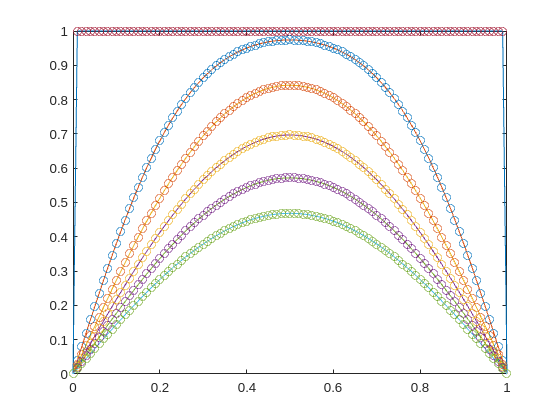

%Grafico sovrapposto%
step = (n_step_time-1)/5;
plot(x, T_sol_exact(:, 1))
hold on
for j = 1:5
    plot(x, T_sol_exact(:,(j)*step));
    hold on
end

scatter(x, T(:, 1))
hold on
for j = 1:5
    scatter(x, T(:,(j)*step));
    hold on
end
hold off

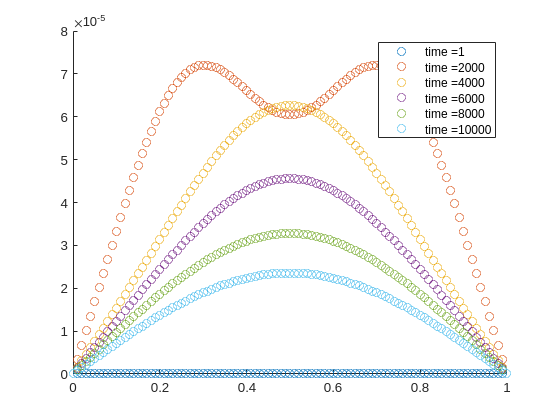



%Differenza tra risultati
Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

step = (n_step_time-1)/5;

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*step));
end

scatter(x, T_sol_exact(:, 1)-T(:,1))
hold on
for j = 1:5
    scatter(x, T_sol_exact(:,(j)*step)-T(:,(j)*step));
    hold on
end
legend(Legend)
hold off